**Load the necessary Modules**

mrstModule add ad-core ad-blackoil ad-eor ad-props incomp

**Setting Up the Geometry**

H (rock depth) = 0.2m,    Nz (Points of the spatial Grid) = 100

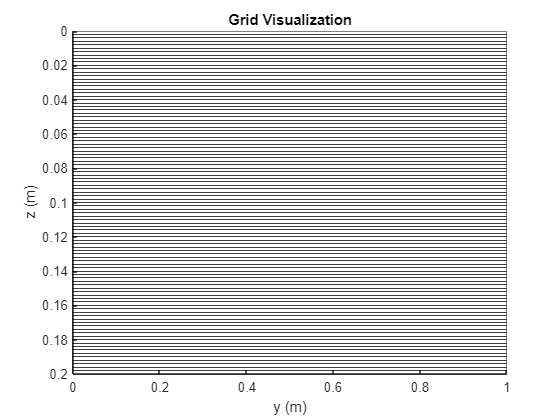

% Step 1: Define the Grid
Nx = 1; % Number of grid cells in the x-direction
Ny = 1; % Number of grid cells in the y-direction
Nz = 100; % Number of grid cells in the z-direction
H = 0.2; % Rock depth (in the z-direction)
Lx = 1; % Length of the domain (in the x-direction)
Ly = 1; % Length of the domain (in the x-direction)
% depth = linspace(0, H, Nz)';
G = cartGrid([Nx, Ny, Nz], [Lx, Ly, H]); % Grid with dimensions [Nx, Ny, Nz] in x-y-z plane

G = computeGeometry(G); % Compute geometry (cell volumes, centroids, face areas, etc.)


% Plot the grid
plotGrid(G,'FaceColor','none','FaceAlpha',.2,'EdgeAlpha',.5);view(90,0);
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
title('Grid Visualization');

**Define Rock and Fluid properties**

*Rock Properties:*

$\varphi_0 =0.3$,    $K_0 =0.02\textrm{∙}{10}^{-12} \ m^2$

*Fluid Properties:*

$\mu_w =\mu_o =0.001\ Pa\textrm{∙}s$,    $\rho_w =1000\frac{kg}{m^3 }$,    $\rho_o =660\frac{kg}{m^3 }$,    $k_{rw}^0 =k_{ro}^0 =1$,    $a=b=4$,    $S_{wr} =S_{or} =0.001$

% Step 2: Define Fluid and Rock Properties
perm = repmat(0.02e-12, G.cells.num, 1); % Define initial absolute permeability
poro = 0.3; % Define porosity
rock = makeRock(G,perm,poro); %define intial absolute permeability and porosity
% plotCellData(G,rock.perm); view(3);

fluid = initSimpleADIFluid('phases', 'WO', ...          %Fluid phases: Water, Oil
                           'mu', [0.001, 0.001], ...    %Viscosities [Pa*s]
                           'rho', [1000, 660], ...      %Densities [kg/m^3]
                           'n', [4, 4], ...             %Monomials
                           'smin', [0.001, 0.001]);     %Irreducible Water Saturation and Residual Oil Saturation

*Capillary Pressure:*

$p_c =b_w ∙{{\left(S+\varepsilon_1 \right)}}^{-a_w } +b_o ∙{{\left(1-S+\varepsilon_2 \right)}}^{-a_o }$,    *N.B. It is defined as an anonymous function of the saturation in the fluid object*

$b_w =500$,    $b_o =-500$,    $a_w =a_o =0.5$

% Define capillary pressure equation parameters
a_w = 0.5; % Pore size distribution index for imbibition
a_o = 0.5; % Pore size distribution index for drainage
b_w = 500; % Constant for entry pressure for imbibition
b_o = -500; % Constant for entry pressure for drainage

fluid.pcOW = @(s,varargin) b_w.*(((s)-s1)/(su-s1) + eps(10)).^(-a_w) + b_o.*(1 - ((s)-s1)/(su-s1) - eps(10).^ (-a_o));

disp(fluid)

**Set up the model**

The model object contains the grid, the fluid and rock properties and the modeling equations.

gravity reset on;
model = OilWaterSurfactantModel (G,rock,fluid);